Ex 10.1


$$T_s =\frac{4}{\zeta \omega_n }$$


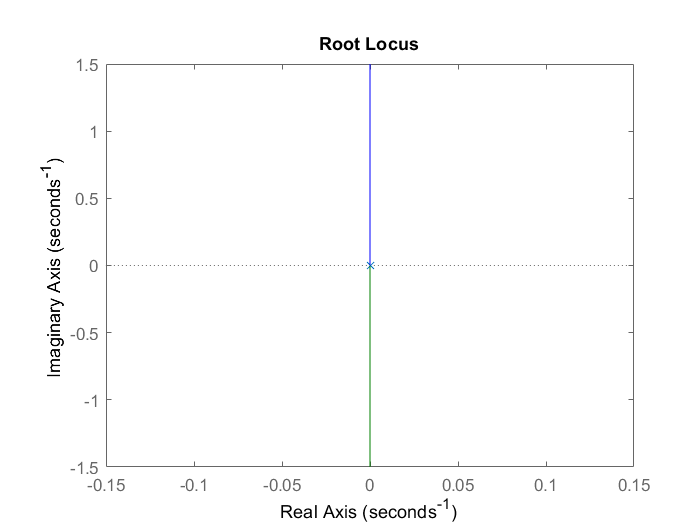

clc; clear; close all;
% G = 10/s^2; H = 1
% specs: Ts<=4s; damping ratio >=0.45
%%%% root locus + phase lead

G = tf(10, [1 0 0]);
figure; rlocus(G);

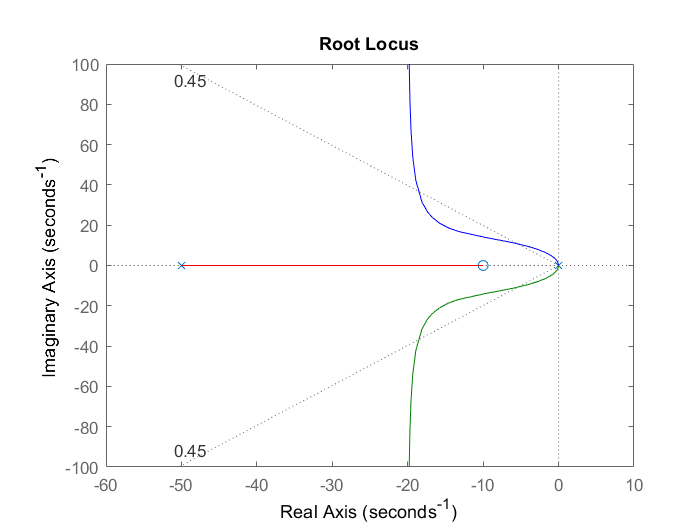


% Compensation
z = 10; p = 50;
Gc = tf([1 z], [1 p]);
L = G*Gc;
% sgrid(zeta,wn)
figure; rlocus(L);
zeta = 0.45; sgrid(zeta, 10^3);


K = 62;
L = K*L;
T = feedback(L,1);
stepinfo(T)

ans = struct with fields:
        RiseTime: 0.0718
    SettlingTime: 0.6122
     SettlingMin: 0.9230
     SettlingMax: 1.4037
       Overshoot: 40.3740
      Undershoot: 0
            Peak: 1.4037
        PeakTime: 0.1989


Ex 10.2 (lead + Bode)

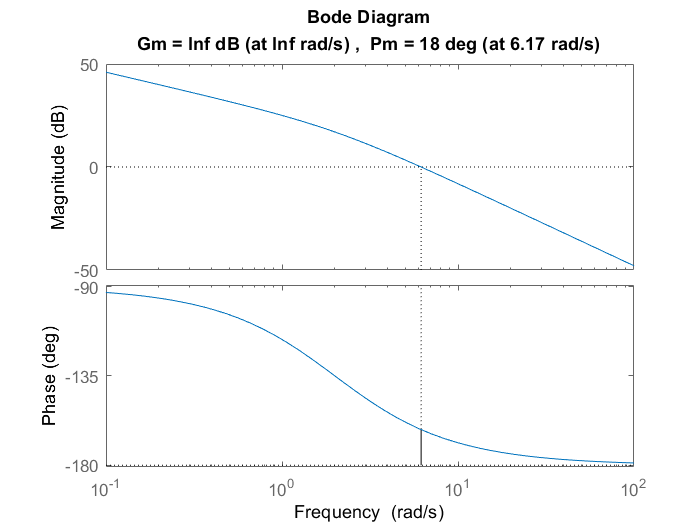

clc;clear;close all;
% L = 40/[s(s+2)]
% specs:   Ess=5% of the velocity of ramp; P.M.= 40
%%%% Bodes + phase lead
% Gc = K*alpha*(s+z)/(s+p)

%%% Bode 
G = tf(40,[1 2 0]);
figure; margin(G);

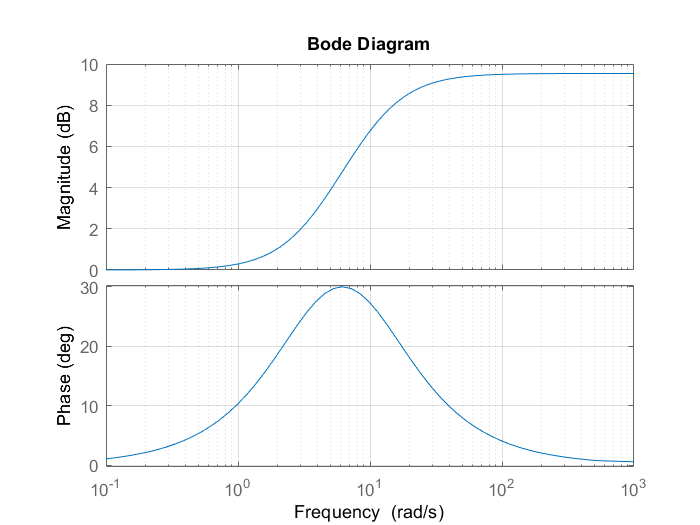


K = 1;  % 1st parameter used to achieve error constant
w_m = 6.17;  % 2nd parameter 
% original PM = 18, need to add at least (40-18) degrees
phi_m = 30;   % 3rd parameter (in degrees)
Gc = Bode_lead(K,phi_m,w_m);
figure; bode(Gc); grid on;

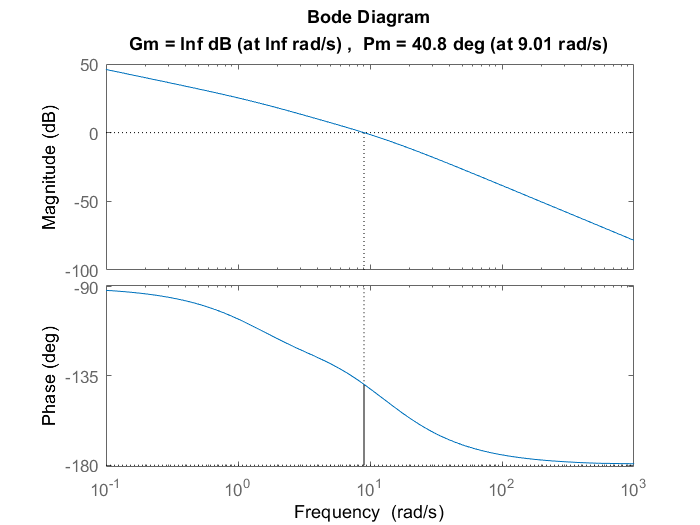


L = G*Gc;
figure; margin(L);

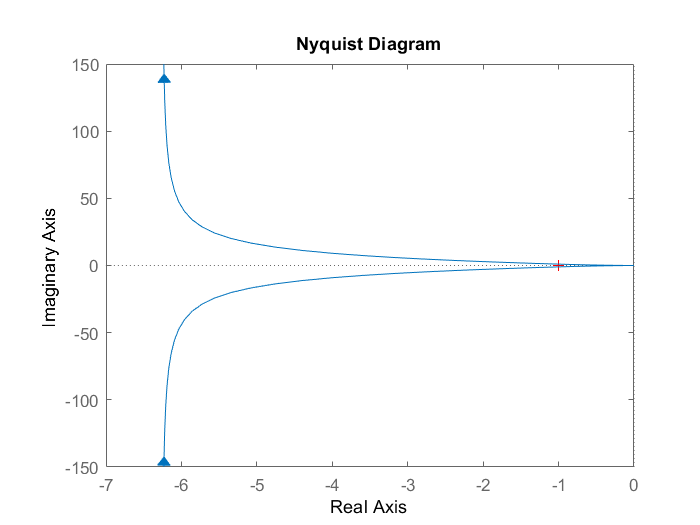

figure; nyquist(L);

Ex 10.2 (lag + Bode)

clc;clear;close all;
% L=40/[s(s+2)]
% specs:   Ess=5% of the velocity of ramp; P.M.= 40
%%%% Bodes + phase lag

%%% Bode 
G=tf(40,[1 2 0]);
figure; margin(G);

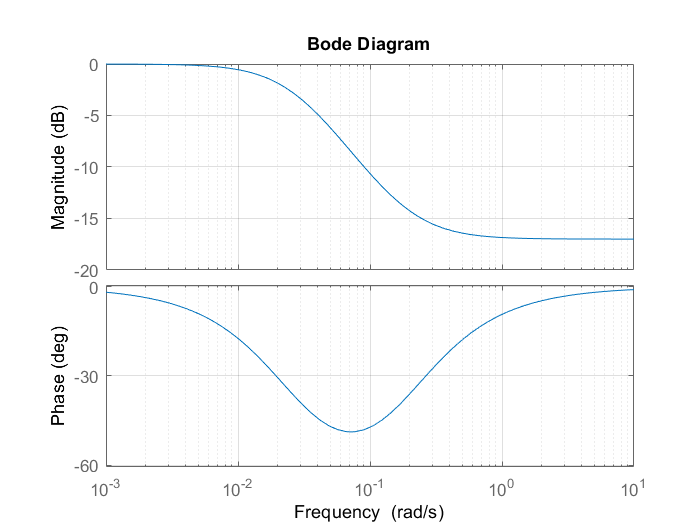


%%% lag
K = 1;
omega_c = 1.91;
attenuation_db = 17;
Gc = Bode_lag(K,omega_c,attenuation_db);
figure; bode(Gc); grid on;

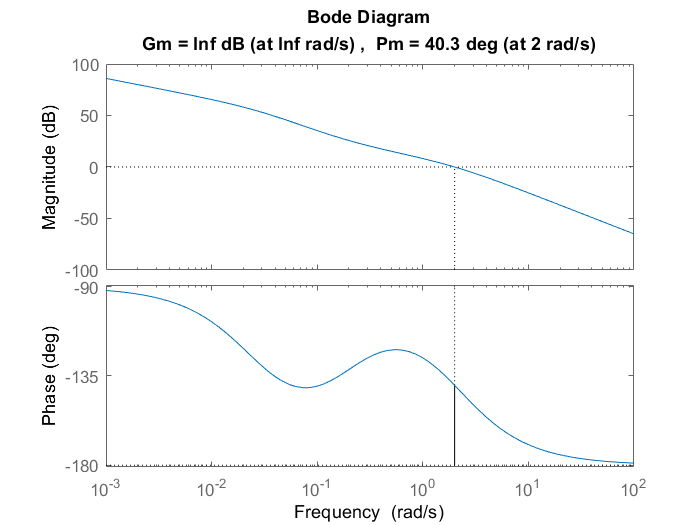


L = Gc * G;
figure; margin(L);

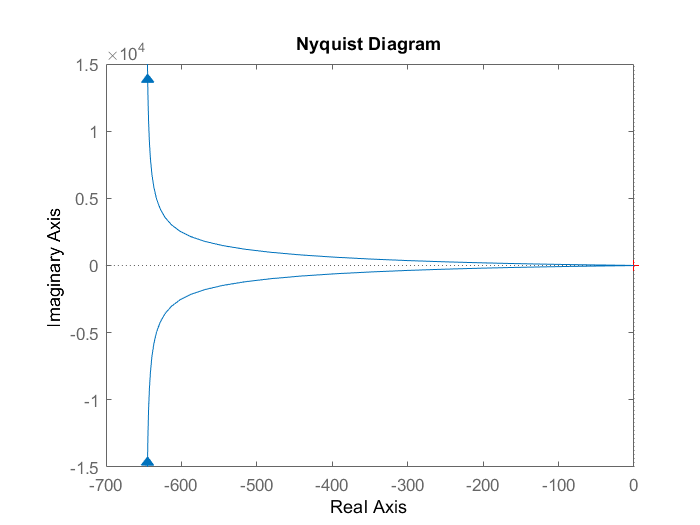

figure; nyquist(L);

Ex 10.2 (lead + RL), RL = root locus


$$\zeta \approx 0\ldotp 01\phi_{\mathrm{PM}} \;\mathrm{for}\;\zeta \le 0\ldotp 7\;\mathrm{and}\;\phi_{\mathrm{PM}} \;\mathrm{in}\;\mathrm{degrees}$$


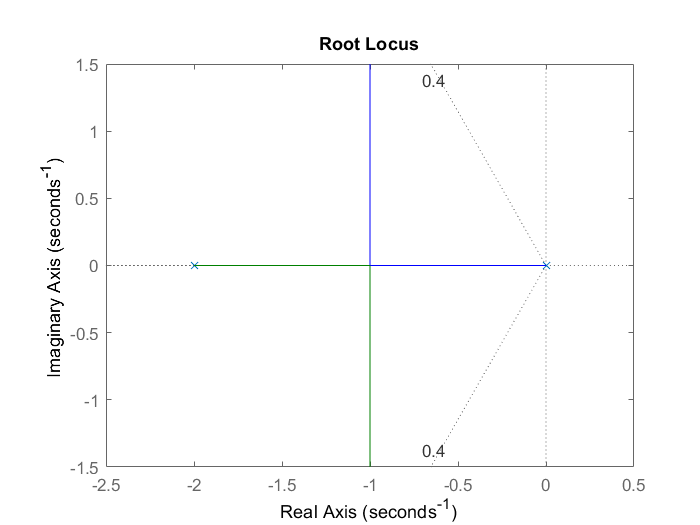

clc;clear;close all;
% L=40/[s(s+2)]
% specs:   Ess = 5% of the velocity of ramp; P.M.= 40

%%% Bode 
G = tf(40,[1 2 0]);
figure; rlocus(G);
zeta = 40*0.01; sgrid(zeta,10^4);

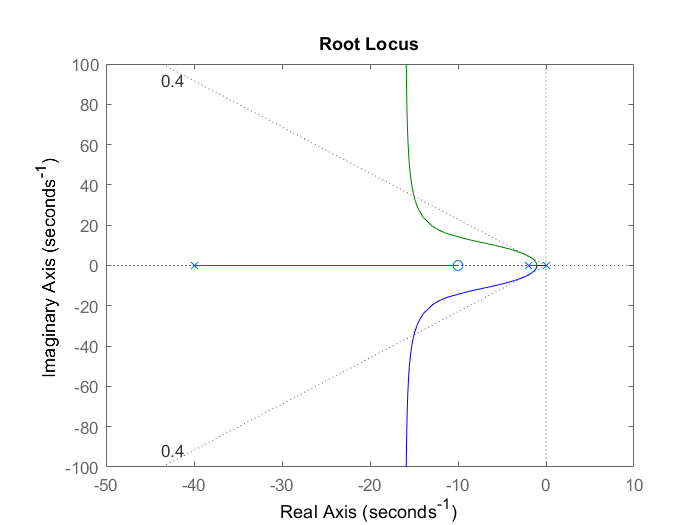

z = 10; p = 40;

Gc=tf([1 z],[1 p]);
L=G*Gc;
figure; rlocus(L);
sgrid(zeta,10^4);

K = p/z;
[~,Phase_margin] = margin(K*L);
Phase_margin

Phase_margin = 40.9466

figure; margin(G);

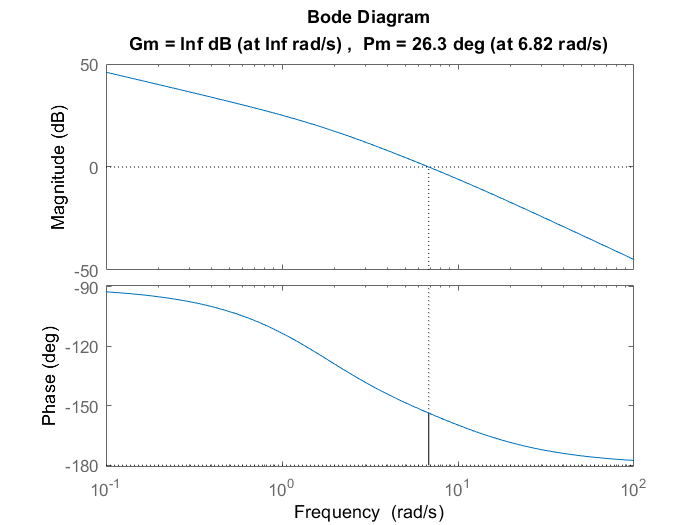


K=1;  % 1st parameter used to achieve error constant
w_m=6.17;  % 2nd parameter 
phi_m=10;   % 3rd parameter (in degrees)
Gc=Bode_lead(K,phi_m,w_m);

L=G*Gc;
figure; margin(L);

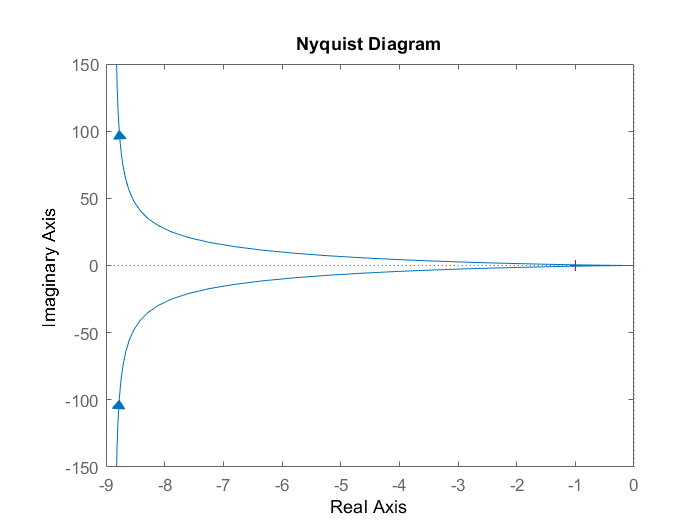

figure; nyquist(L);

Ex 10.2 (lag + RL), RL = root locus

clc;clear;close all;
% L=40/[s(s+2)]
% specs:   Ess=5% of the velocity of ramp; P.M.= 40

%%% Bode 
G = tf(40,[1 2 0]);
figure; rlocus(G);
zeta=40*0.01; sgrid(zeta,10^4);

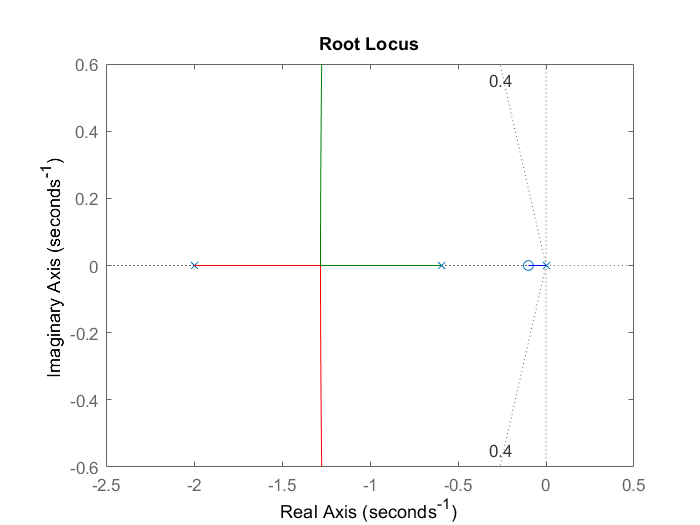


K = 0.168;  % determined by the requirement on P.M.
my_alpha = K;  %  determined by the requirement on error constant
z = 0.1; p = z/my_alpha;

Gc = tf([1 z],[1 p]);
L = G*Gc;
figure; rlocus(L);
sgrid(zeta,10^4);


[~,Pm] = margin(K*L);
Pm

Pm = 55.0102

Ex 10.3 Lead + Root

$T_S =\frac{4}{\zeta \omega_n }$, $P\ldotp O\ldotp =100%\times e^{-\frac{\zeta \pi }{\sqrt{1-\zeta^2 }}}$

Phase Lead only since we want to reshape the root locus. 

clc;clear;close;

%%% specs
%%% Ts<=4, P.O<=35%

G = tf(1,[1 0 0]);

figure; rlocus(G);


zeta = 0.35;
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5)

PO = 30.9190

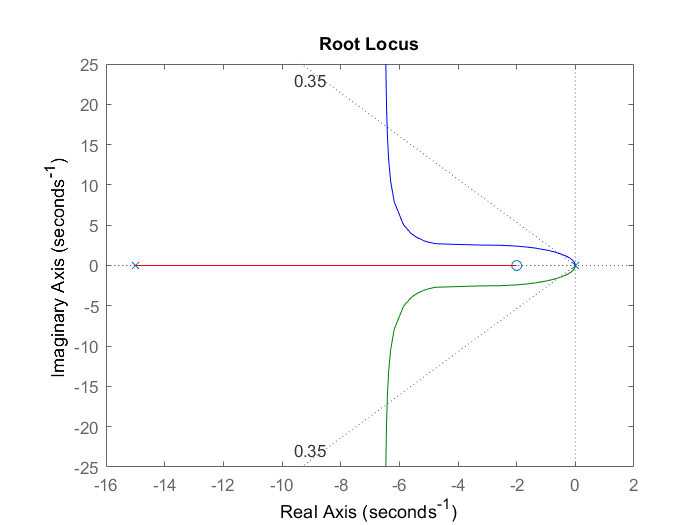


z = 2; p = 15; Gc = tf([1 z],[1 p]);
L = Gc*G;

figure; rlocus(L);
sgrid(zeta,10^4); % sgrid(zeta,wn)

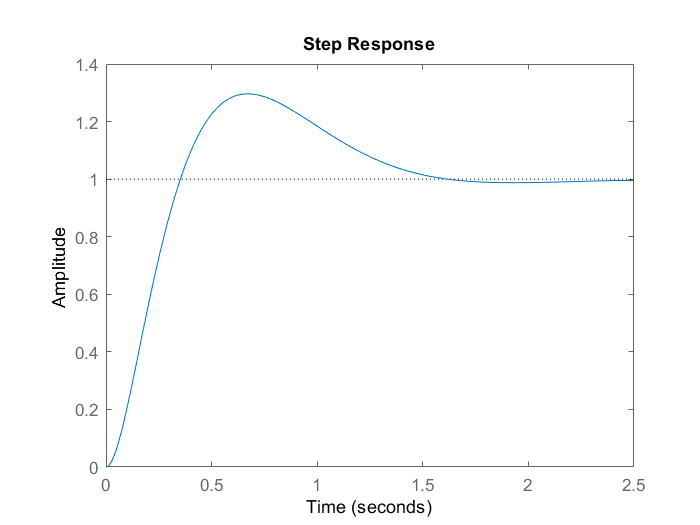


K = 63;
L = K*Gc*G;
T = feedback(L,1);
figure; step(T);


S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.2457
    SettlingTime: 1.4709
     SettlingMin: 0.9128
     SettlingMax: 1.2963
       Overshoot: 29.6312
      Undershoot: 0
            Peak: 1.2963
        PeakTime: 0.6674


Ex 10.4 Lead + Root


$$K_v \ge 20,K_v =\lim_{s\longrightarrow 0} \textrm{sL}\left(s\right)=\lim_{s\longrightarrow 0} \textrm{sK}\left(\frac{s+z}{s+p}\right)\frac{1}{s\left(s+2\right)}=K\frac{z}{p}\frac{1}{2}\ge 20$$



$$G\left(s\right)=\frac{1}{s\left(s+2\right)},\;\textrm{Gc}\left(s\right)=K\left(\frac{s+z}{s+p}\right)$$


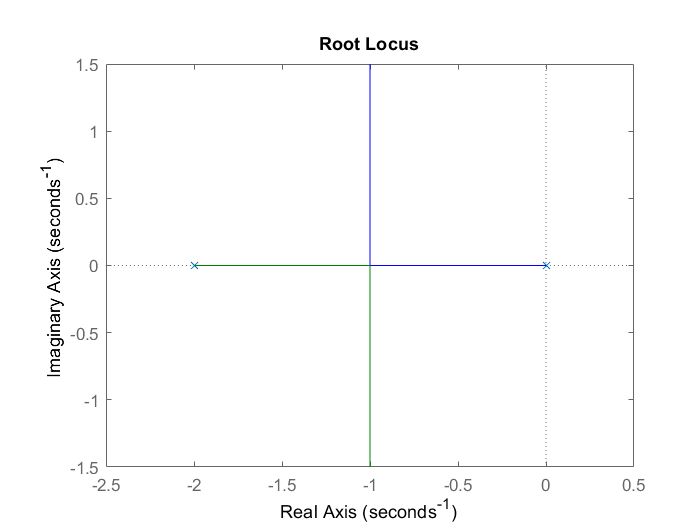

clc;clear;close all;

%%% Requirement
% damping ratio>=0.45, K_gc>=40

%%% Specs
% damping ratio = 0.45, error constant>=20

G = tf(1,[1 2 0]);
damp = 0.45;
figure; rlocus(G); % --> zero want to set at (<-2)

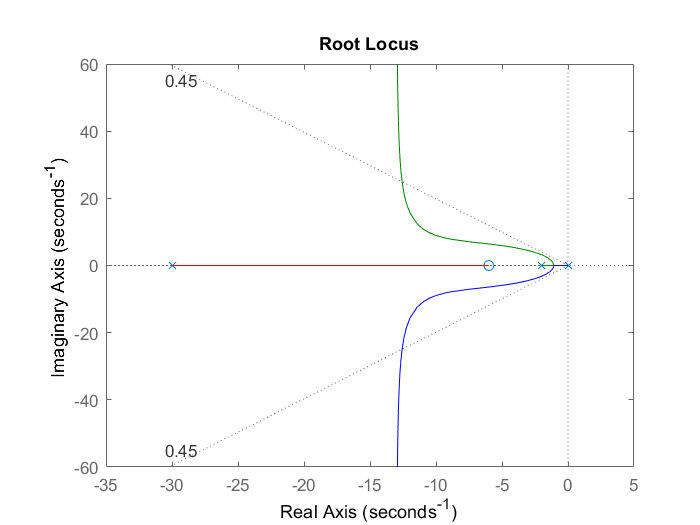


% % % compensation
z = 6; p = 30;
Gc = tf([1 z],[1 p]);

L = Gc*G;
figure; rlocus(L); sgrid(damp,10^4);

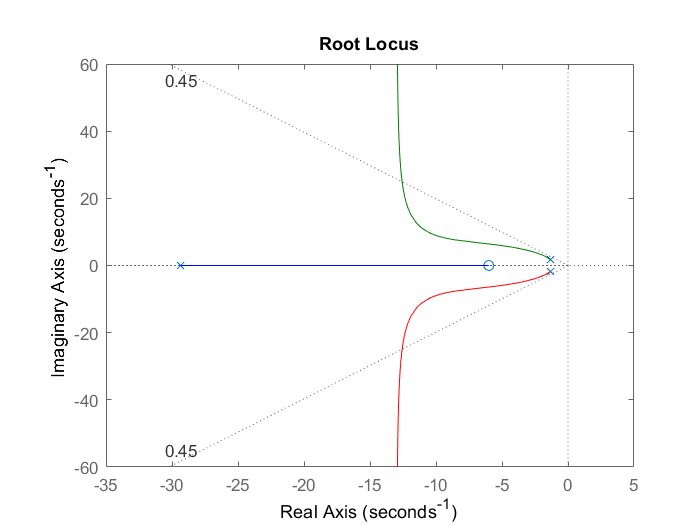


K_min = p/z; % K>=p/z to satisfy the Kv>=20
Kc = 22.5;

T = feedback(Kc*L,1);
figure; rlocus(T); sgrid(damp,10^4);

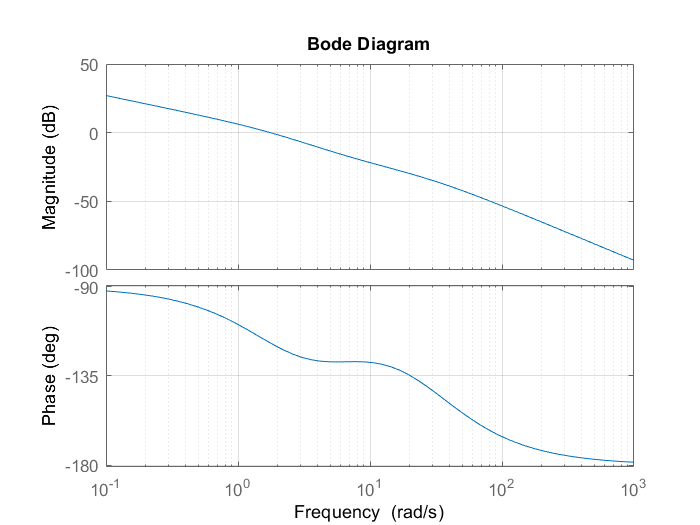

figure; bode(Kc*L); grid on;


S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.8172
    SettlingTime: 2.6392
     SettlingMin: 0.9059
     SettlingMax: 1.0913
       Overshoot: 9.1257
      Undershoot: 0
            Peak: 1.0913
        PeakTime: 1.7001


Ex 10.4 Lag + Root

此設計的pole不會影響到domiant pole，因為此設計會伴隨很接近此polo，會有zero pole cancellation的情形。

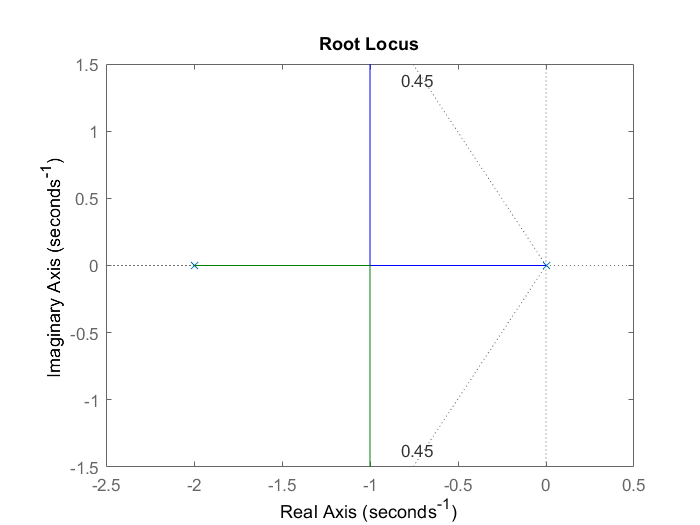

clc;clear;close all;

G = tf(1,[1 2 0]);
damp = 0.45;
figure; rlocus(G); sgrid(damp,10^4);

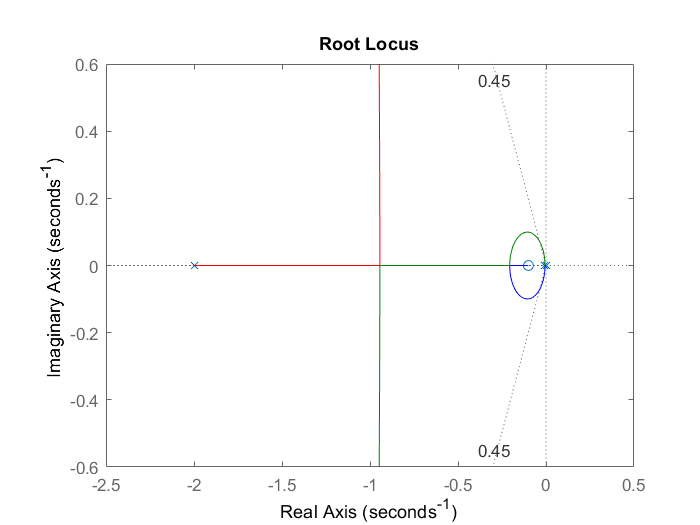


% % % compensation
Kc = 4.41; % gain of G at damping ratio close to 0.45
alpha = 40/Kc; % alpha = z/p

% To meet the requirement of error constant > 20
z = 0.1; p = z/alpha;

Gc = Kc*tf([1 z],[1 p]);
L = Gc*G;
figure; rlocus(L/Kc); sgrid(damp,10^4);

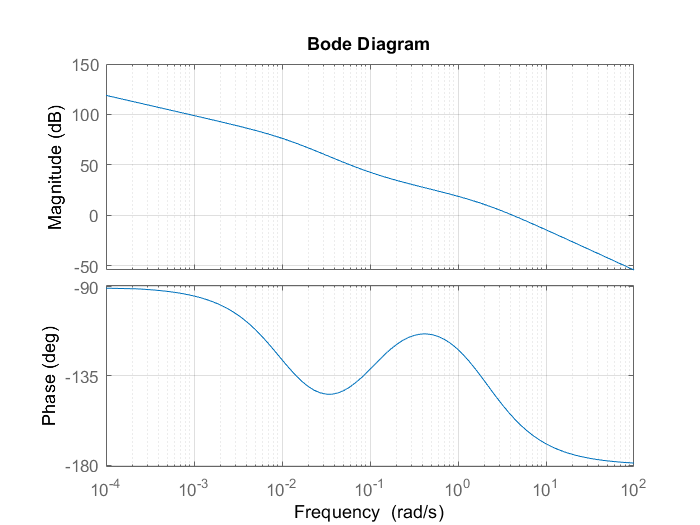

figure; bode(Kc*L); grid on;


T = feedback(Kc*L,1);
S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.2778
    SettlingTime: 3.9378
     SettlingMin: 0.7599
     SettlingMax: 1.5088
       Overshoot: 50.8798
      Undershoot: 0
            Peak: 1.5088
        PeakTime: 0.7233


Ex 10.7 Lead + Root


$$K_v \ge 20,K_v =\lim_{s\longrightarrow 0} \textrm{sL}\left(s\right)=\lim_{s\longrightarrow 0} \textrm{sK}\left(\frac{s+z}{s+p}\right)\frac{1}{{s\left(s+10\right)}^2 }=K\frac{z}{p}\frac{1}{100}\ge 20$$



$$G\left(s\right)=\frac{1}{{s\left(s+10\right)}^2 },\;\textrm{Gc}\left(s\right)=K\left(\frac{s+z}{s+p}\right)$$


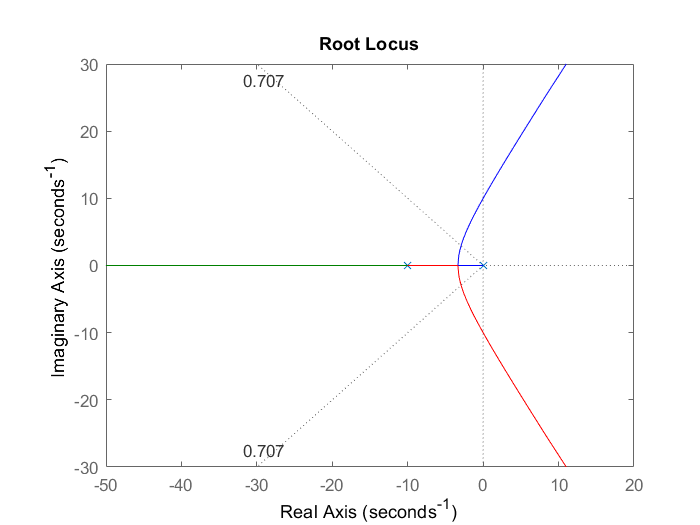

clc;clear;close all;

%%% Requirement
% damping ratio>=0.45, K_gc>=40

%%% Specs
% damping ratio = 0.707, error constant>=20

den1 = conv([1 10], [1 10]); den = conv([1 0], den1);
G = tf(1,den);
zeta = 0.707;
figure; rlocus(G); sgrid(zeta,10^4);

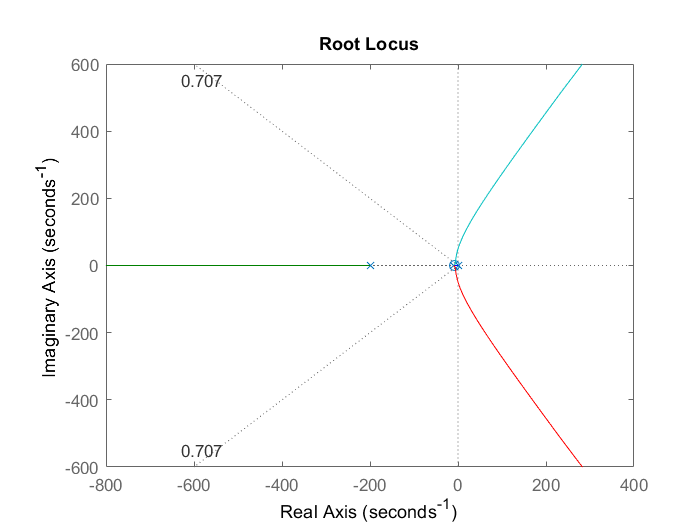


% % It's difficult to increase the error constant
% % % compensation
z = 8; p = 200;
K = 2000*p/z; % Kv>=20
Gc = K*tf([1 z],[1 p]);

L = Gc*G;
figure; rlocus(L/K); sgrid(zeta,10^4);

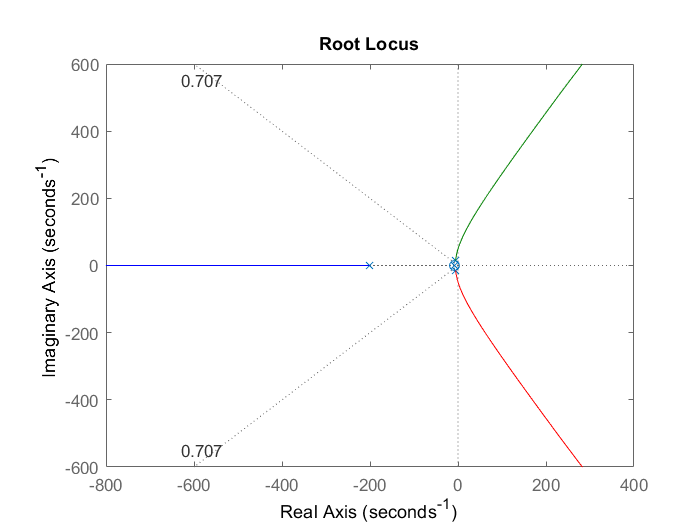


K_min = p/z; % K>=p/z to satisfy the Kv>=20
Kc = 30;

T = feedback(L,1);
figure; rlocus(T); sgrid(zeta,10^4);

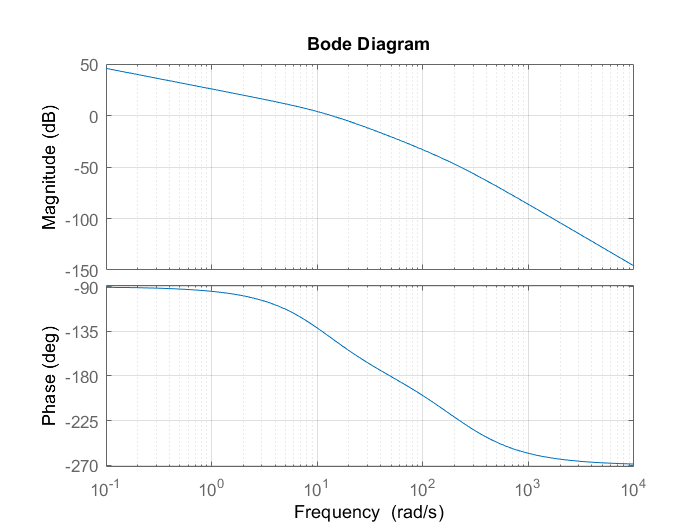

figure; bode(L); grid on;


S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.0881
    SettlingTime: 0.6995
     SettlingMin: 0.8988
     SettlingMax: 1.3093
       Overshoot: 30.9338
      Undershoot: 0
            Peak: 1.3093
        PeakTime: 0.2127


Ex 10.7 Lag + Root

clc;clear;close all;

G = tf(1, conv([1 10 0], [1 10]));
damp = 0.707;
figure; rlocus(G); sgrid(damp,10^4);

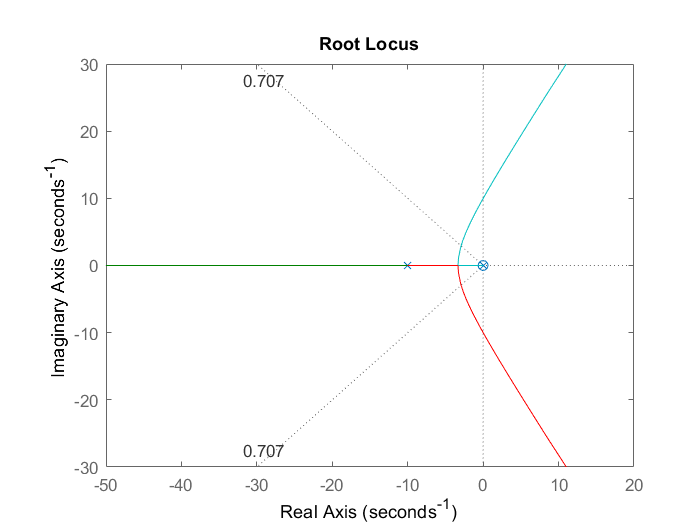


% % % compensation
Kc = 241; % gain of G at damping ratio close to 0.707
alpha = 2000/Kc; % alpha = z/p

% To meet the requirement of error constant > 20
z = 0.01; p = z/alpha;

Gc = Kc*tf([1 z],[1 p]);
L = Gc*G;
figure; rlocus(L/Kc); sgrid(damp,10^4);

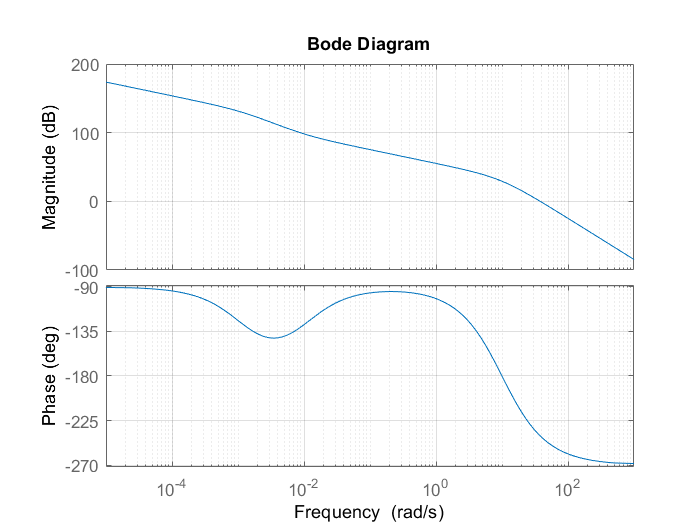

figure; bode(Kc*L); grid on;


T = feedback(L,1);
S = stepinfo(T)

S = struct with fields:
        RiseTime: 0.5452
    SettlingTime: 1.5695
     SettlingMin: 0.9122
     SettlingMax: 1.0432
       Overshoot: 4.3219
      Undershoot: 0
            Peak: 1.0432
        PeakTime: 1.1783



% % % Check specs
C = tf([1 0], 1)*L;
Kv = evalfr(C, 10^-10)

Kv = 20.0000

Ex 10.8 Lag + Bode

clc;clear;close all;

%%% step 1
K = 40; % Kv>=20
G = tf(1,[1 2 0]);
figure; margin(K*G);

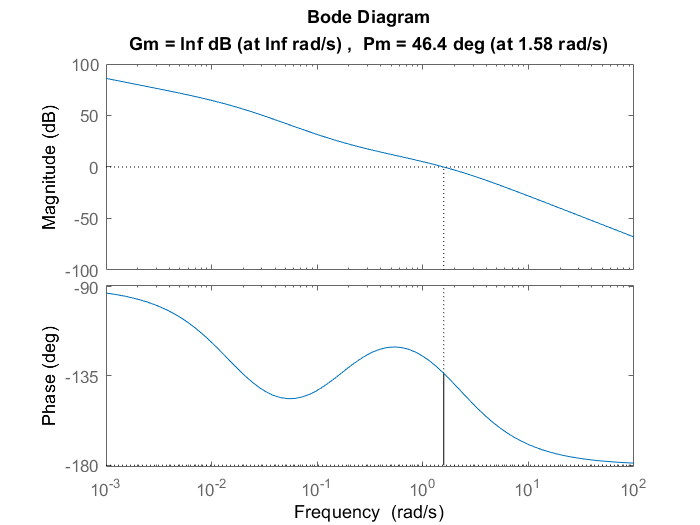

omega_c = 1.65;
attenuation_db = 20;

Gc = Bode_lag(K,omega_c,attenuation_db);

%%% step 2
L = Gc * G;
figure; margin(L);

Ex 10.5 PI + Root

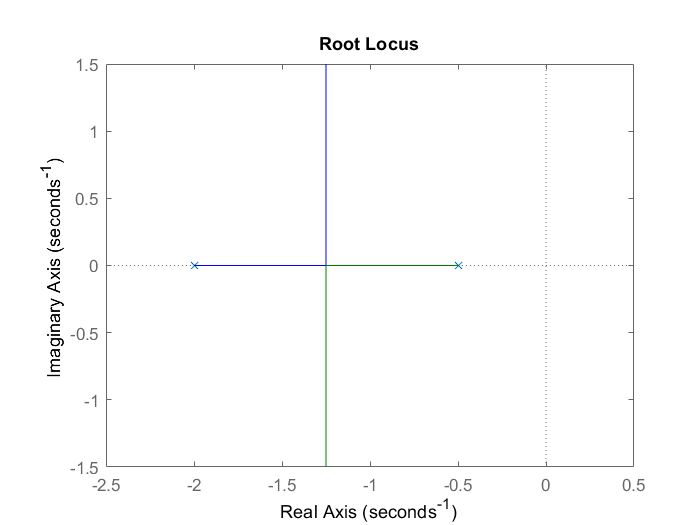

clc;clear;close all;

%%% Specs
%% G = 1/(s+0.5)(s+2)
%% e_ss for step input = 0
%% P.O. <= 20%
%% Gc = K(s+z)/s (PI Compensator)

G = tf(1, conv([1 0.5], [1 2]));
figure; rlocus(G);


zeta = 0.46; 
PO = 100*exp(-zeta*pi/(1-zeta^2)^0.5)

PO = 19.6410

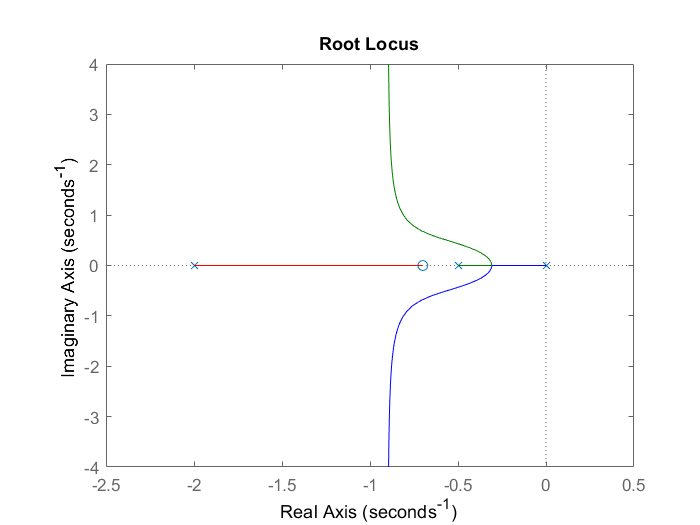


z = 0.7;
Gc = tf([1 z], [1 0]);
L = G*Gc;
figure; rlocus(L);


%%% Check specs
K = 2.8;
T = feedback(K*L, 1);
syst = stepinfo(T);
syst.Overshoot

ans = 19.2625

e_ss = evalfr(T-1, 0) % lim s(Y-R) as s->0

e_ss = 0

function [Gc] = Bode_lead(K, phi_m, wm)
    phi = phi_m*pi/180;
    a = (1+sin(phi))/(1-sin(phi));
    p = wm*(a^0.5); z = p/a;
    Gc = tf((K*(p/z)*[1 z]), [1 p]);
end

function [Gc] = Bode_lag(K, wc, M)
    a = 10^(M/20);
    z = wc/10; p =z/a;
    Gc = tf((K*(p/z)*[1 z]), [1 p]);
end